**1 Segmentierung, Schwellwerte, Histogramme (ca. 20-30 Min)**

Der Ordner „Muttern“ enthält mehrere Bilder von Muttern, die im Durchlichtverfahren erstellt worden sind. Ziel ist es, die Anzahl der Muttern im Bild zu bestimmen. Lesen sie zunächst das Bild "Muttern_2_1.png" ein (`imread`).

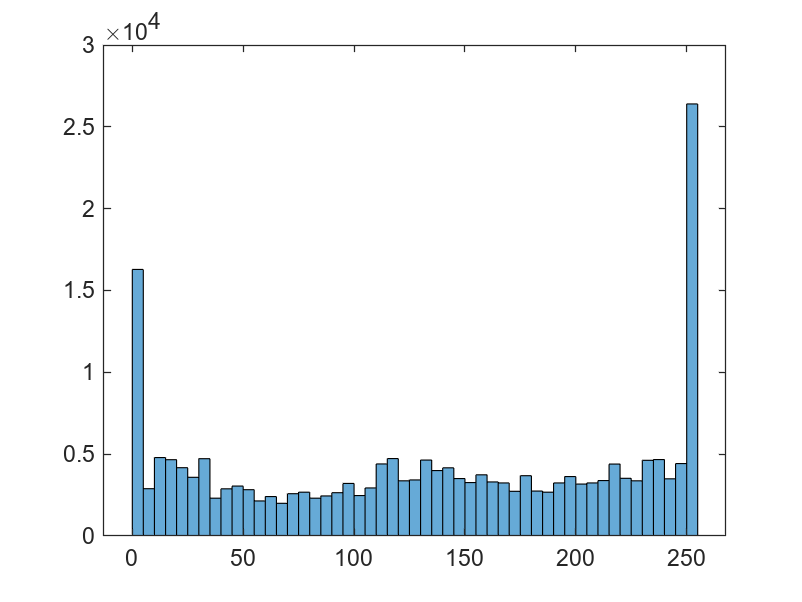

% imtool
I_1_1 = imread('./Muttern/Muttern_1_1.png');
I_1_2 = imread('./Muttern/Muttern_1_2.png');
I_2_1 = imread('./Muttern/Muttern_2_1.png');
I_2_2 = imread('./Muttern/Muttern_2_2.png');
I_2_3 = imread('./Muttern/Muttern_2_3.png');
I_3_1 = imread('./Muttern/Muttern_3_1.png');
I_3_2 = imread('./Muttern/Muttern_3_2.png');
I_3_3 = imread('./Muttern/Muttern_3_3.png');
I_3_4 = imread('./Muttern/Muttern_3_4.png');
b1 = imread("./bild1.jpg");
b2 = imread("./bild2.jpg");
histogram(b1);

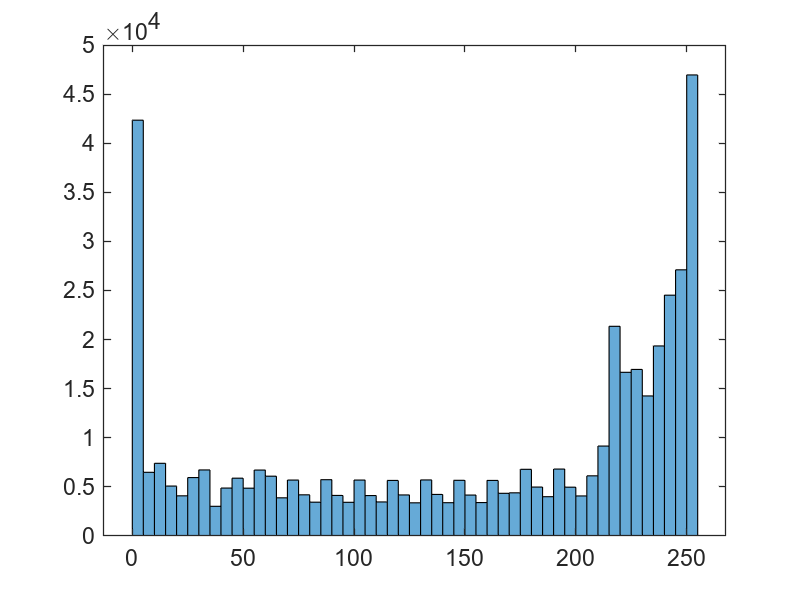

histogram(b2);

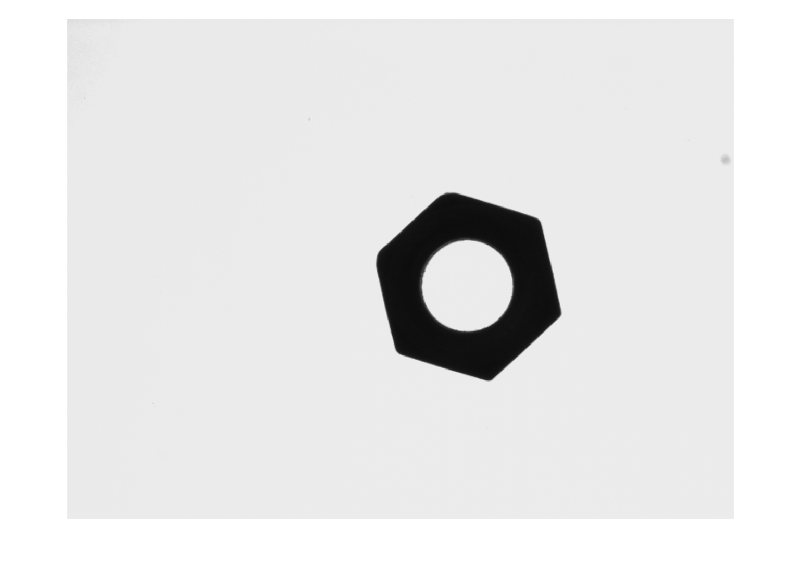

imshow(I_1_1);

- Nutzen Sie die Funktion h`istogram`, um die Grauwertverteilung des Bildes darzustellen.

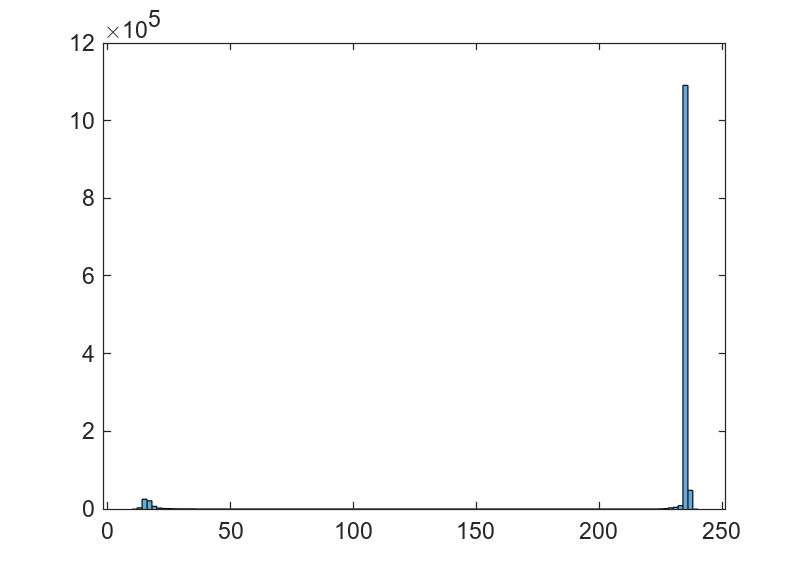

h_1_1 = histogram(I_1_1);

- Segmentieren Sie die Muttern mit Hilfe der Funktion `imbinarize`. Bestimmen Sie einen Schwellwert anhand des Histogramms. Lassen Sie sich das erzeugte Binärbild anzeigen.

% 大于125的地方为白（1），小于为黑（0）
M=graythresh(I_1_1) %自动获取阈值

M = 0.4980

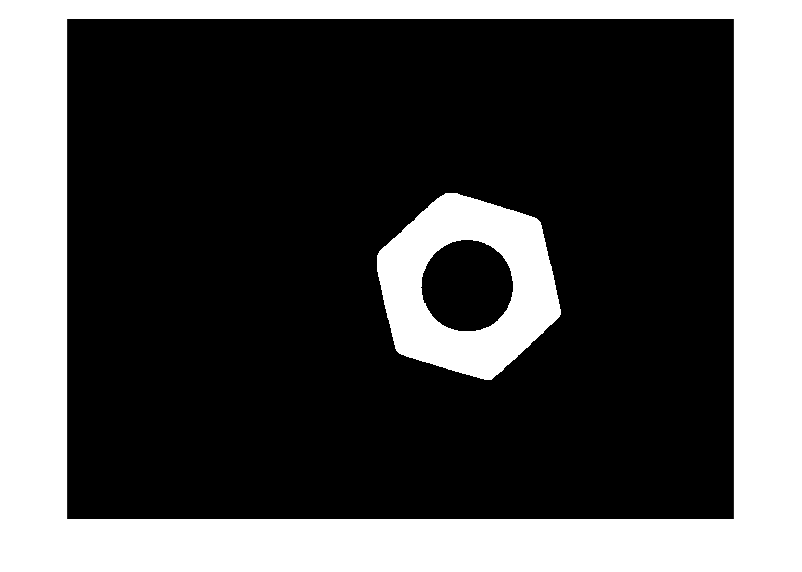

imb_1_1 = ~imbinarize(I_1_1, M);
imshow(imb_1_1);

- Die segmentierte Fläche ist jetzt hell dargestellt. Wie kann der Code einfach verändert werden, dass statt des Hintergrundes die Mutter segmentert wird?

- Nutzen Sie die Funktion `imoverlay`, um die segmentierte Fläche im ursprünglichen Bild farbig darzustellen.

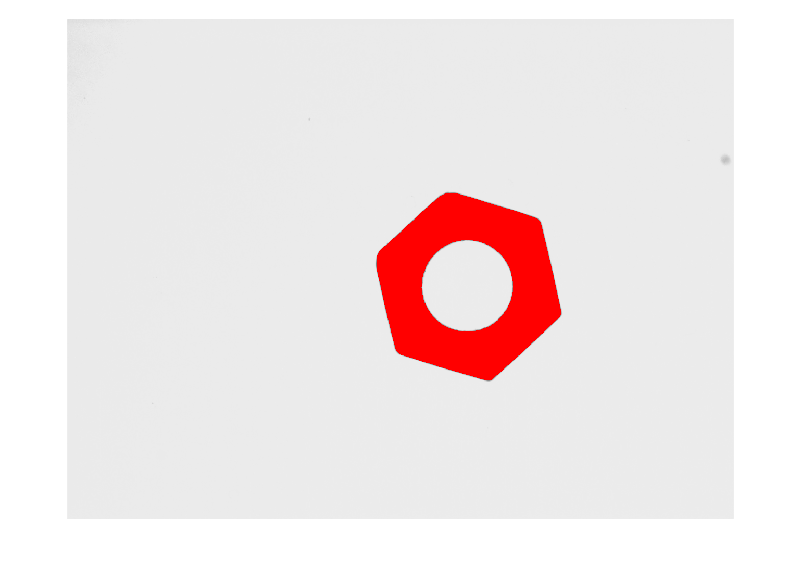

imo = imoverlay(I_1_1,imb_1_1, 'red');
imshow(imo);

- Kann aus dem Mittelwert des Bildes (`mean`) auf die Anzahl der Muttern im Bild geschlossen werden? Verwenden Sie dazu die verschiedenen Bilder im Ordner "Muttern". Untersuchen Sie auch das Binärbild. 

- Nein, der Mittelwert eines Bildes (auch "mean" genannt) gibt lediglich an, welcher durchschnittliche Helligkeitswert im Bild vorliegt. Er sagt nichts über die Anzahl von Objekten im Bild aus, wie zum Beispiel Muttern.

- Um die Anzahl von Muttern im Bild zu bestimmen, müssten spezielle Computer Vision-Algorithmen verwendet werden, die in der Lage sind, die Muttern im Bild zu erkennen und zu zählen. Diese Algorithmen würden das Bild analysieren und anhand von bestimmten Merkmalen, wie zum Beispiel der Form und Größe der Muttern, versuchen, diese im Bild zu identifizieren und zu zählen. Der Mittelwert des Bildes hingegen würde in diesem Fall keine Rolle spielen.

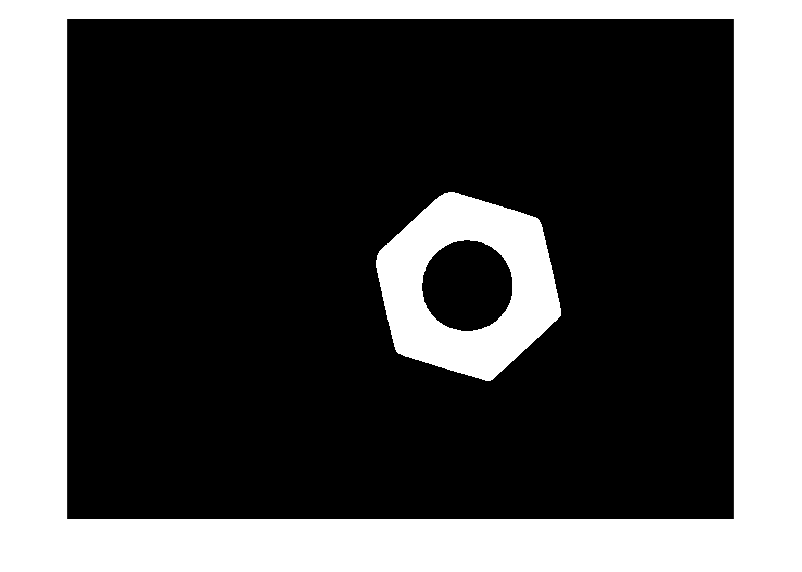

%  m1 = mean(I_1_1)
%  m2 = mean(I_2_1)
%  m3 = mean(I_3_1)
%  m4 = mean(I_1_1)

f = @(x) sum(x(:)) >= 3;
lut = makelut(f,3);
lut1 = bwlookup(imb_1_1,lut);
imshow(lut1)

- Nutzen Sie die Funktion `bwconncomp`, um die Anzahl der verbundenen Regionen im Binärbild, also die Anzahl der Muttern, zu bestimmen.

% 查找二值图像中的连通分量并对其计数
an_1_1 = bwconncomp(imb_1_1)

an_1_1 = struct with fields:
    Connectivity: 8
       ImageSize: [960 1280]
      NumObjects: 1
    PixelIdxList: {[68550×1 double]}


imb_2_1 = ~imbinarize(I_2_1,0.5);
an_2_1 = bwconncomp(imb_2_1)

an_2_1 = struct with fields:
    Connectivity: 8
       ImageSize: [960 1280]
      NumObjects: 2
    PixelIdxList: {[68944×1 double]  [68472×1 double]}


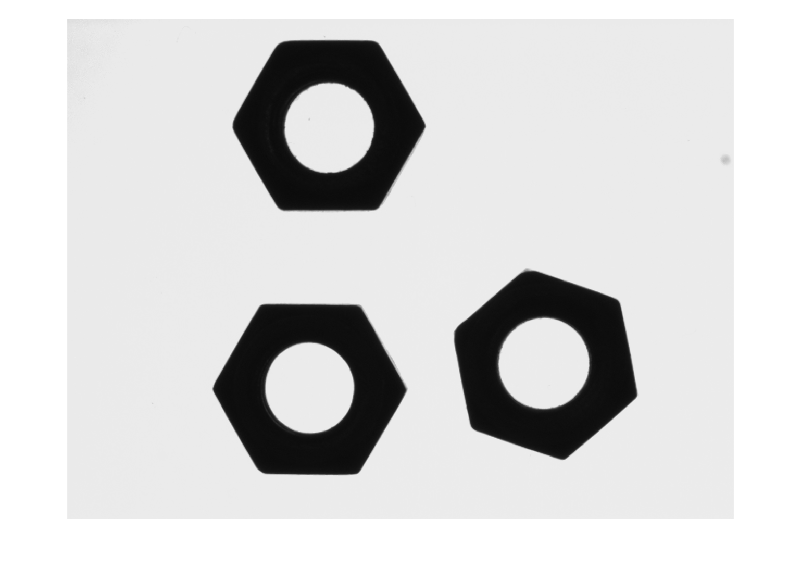

imshow(I_3_1)

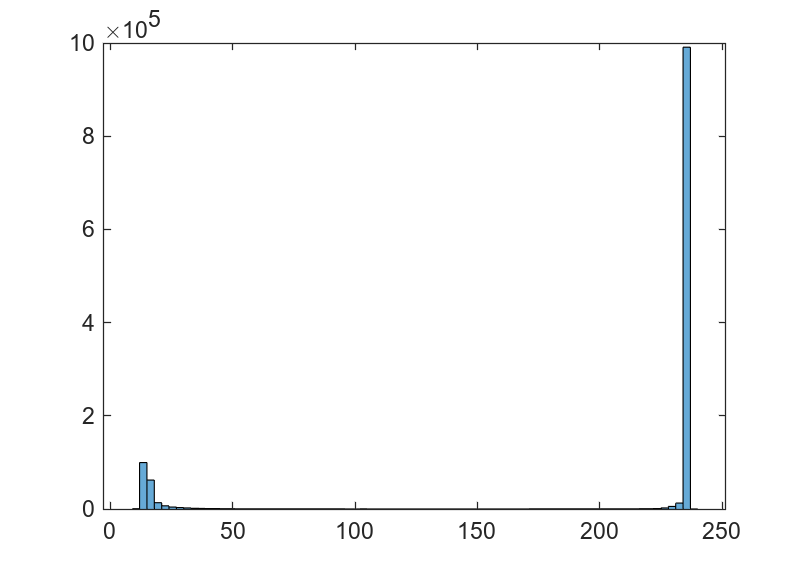

h_3_1 = histogram(I_3_1);

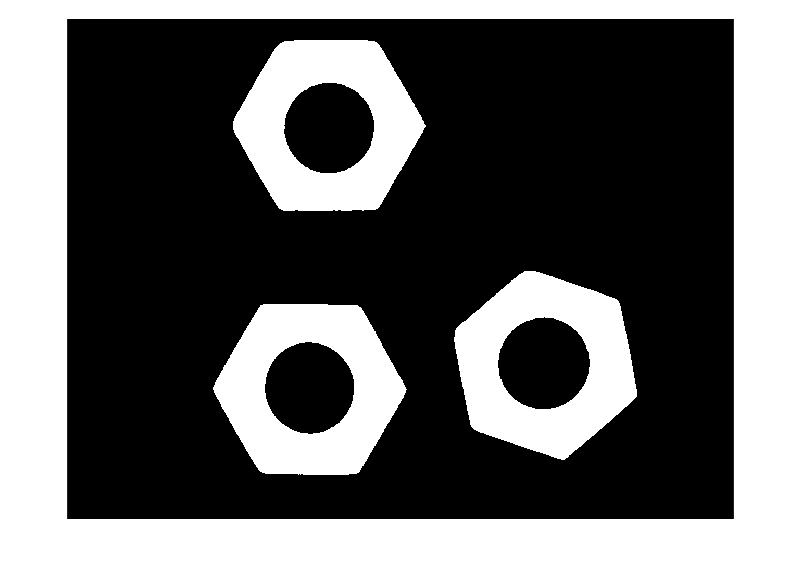

imb_3_1 = ~imbinarize(I_3_1,0.5);
imshow(imb_3_1)

an_3_1 = bwconncomp(imb_3_1)

an_3_1 = struct with fields:
    Connectivity: 8
       ImageSize: [960 1280]
      NumObjects: 3
    PixelIdxList: {[68823×1 double]  [68642×1 double]  [68542×1 double]}


- Im Ordner befinden sich einige Bilder, bei denen die Aufnahmeparameter nicht korrekt eingestellt wurden, oder die Muttern nicht ideal platziert wurden. Diskutieren Sie die Robustheit der Verfahren gegenüber solchen Veränderungen!

- Die Robustheit von Computer Vision-Verfahren, wie sie zur Erkennung von Muttern in einem Bild verwendet werden könnten, hängt in erster Linie von der Qualität der verwendeten Bilder ab. Wenn die Aufnahmeparameter nicht korrekt eingestellt sind, oder die Muttern nicht ideal platziert wurden, kann dies dazu führen, dass die Algorithmen Schwierigkeiten haben, die Muttern im Bild zu erkennen und zu zählen.

- Um die Robustheit der Verfahren zu verbessern, kann es hilfreich sein, **die Bilder vor der Analyse zu bearbeiten, **um sie besser geeignet für die Algorithmen zu machen. Zum Beispiel **könnte man das Bild aufhellen, um die Muttern besser sichtbar zu machen, oder bestimmte Bereiche des Bildes hervorheben,** **in denen die Muttern vermutet werden. Auch die Verwendung von mehreren Bildern desselben Mutter, die aus verschiedenen Perspektiven aufgenommen wurden, kann dazu beitragen, die Robustheit der Verfahren zu verbessern.** 

- Es ist jedoch wichtig zu beachten, dass es immer Grenzen für die Robustheit von Computer Vision-Verfahren gibt. Wenn die Bilder sehr verwackelt oder unscharf sind, oder die Muttern sehr klein oder ungewöhnlich geformt sind, könnten die Algorithmen Schwierigkeiten haben, die Muttern zu erkennen und zu zählen. In solchen Fällen kann es notwendig sein, die Verfahren anzupassen oder alternative Methoden zu verwenden.

**2 Grenzen von Schwellwertoperationen, inhomogene Punktoperatoren (ca. 30-45 Min)**

Die Segmentierung der Muttern stellte sich als verhältnismäßig einfach heraus. Nun schauen wir uns ein etwas schwierigeres Beispiel an, und zwar die Segmentierung eines Pumpengehäuses. Die zugehörigen Bilder finden Sie im Ordner „Pumpengehäuse“.

- Versuchen Sie analog zur Aufgabe 1 das Pumpengehäuse aus „Bild 1“ mit Hilfe eines Schwellwertoperators zu segmentieren. Welche Probleme treten bei der Segmentierung auf?

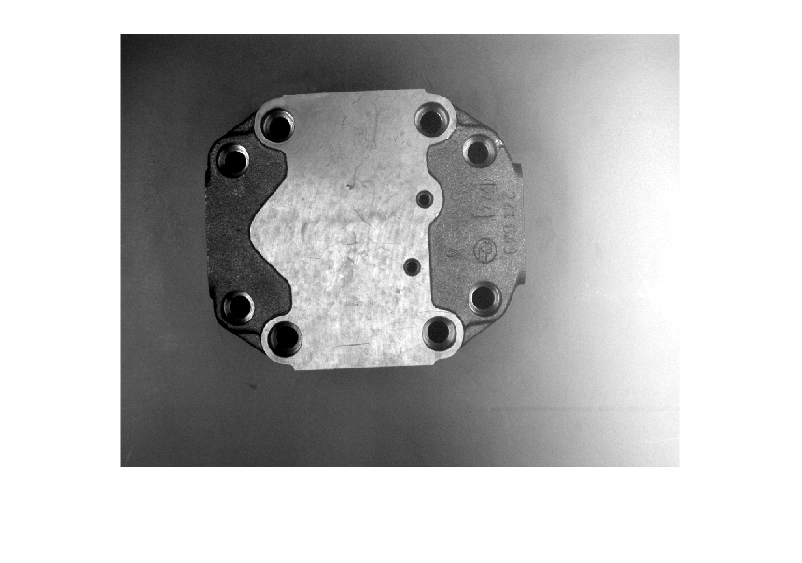

bild1 = imread("./Pumpengehaeuse/Bild1.png");
bild2 = imread("./Pumpengehaeuse/Bild2.png");
bild3 = imread("./Pumpengehaeuse/Bild3.png");
bild4 = imread("./Pumpengehaeuse/Bild4.png");

adj1 = imadjust(bild1);
imshow(adj1);

% histeq = histeq(bild1);
% imshow(histeq)
M=graythresh(adj1) 

M = 0.5392

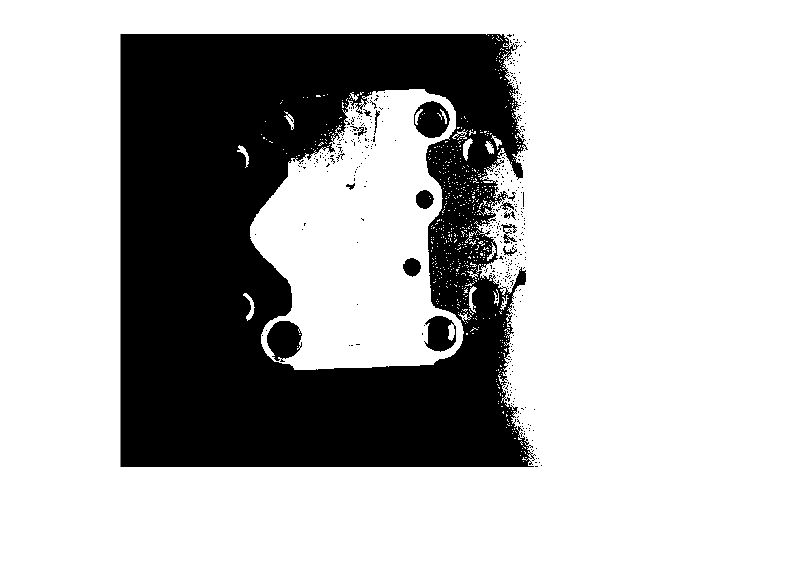

imb_1 = imbinarize(adj1,M);
imshow(imb_1);

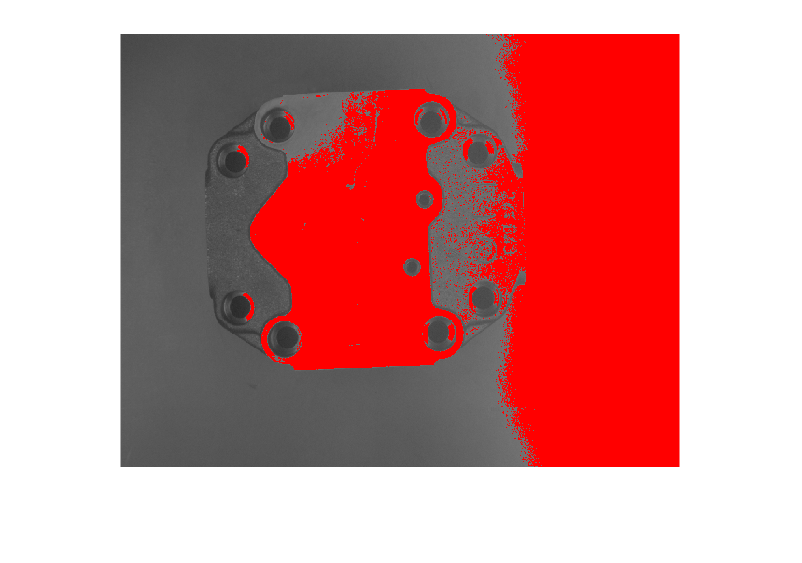

imo_1 = imoverlay(bild1, imb_1, 'red');
imshow(imo_1);

an_1_1 = bwconncomp(imb_1)

an_1_1 = struct with fields:
    Connectivity: 8
       ImageSize: [464 599]
      NumObjects: 662
    PixelIdxList: {1×662 cell}


- Nutzen Sie nun das „Bild 2“, um eine Subtraktion des Hintergrunds durchzuführen. Nach der Subtraktion können Sie wiederum einen Schwellwert zur Segmentierung anwenden. Vergleichen Sie auch das Histogramm vor und nach der Subtraktion.

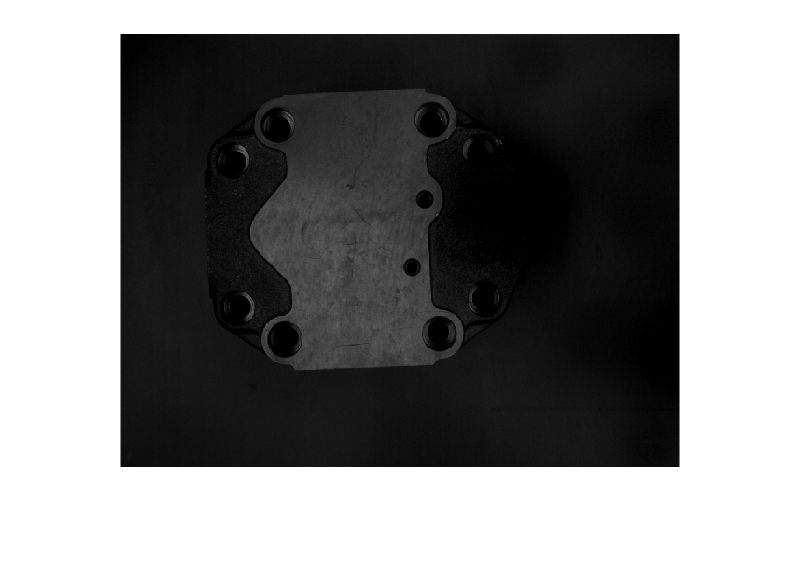

%开运算属于形态学图像处理，是先腐蚀后膨胀。对图像实现开运算，一般能平滑图像的轮廓，消弱狭窄的部分，去掉细的突出，保持面积大小不变等。
% background = imopen(bild2,strel('disk',20)); % 创建圆盘半径1
% bild_sub = imsubtract(background, bild2);
bild_sub = bild1 - bild2;
imshow(bild_sub);

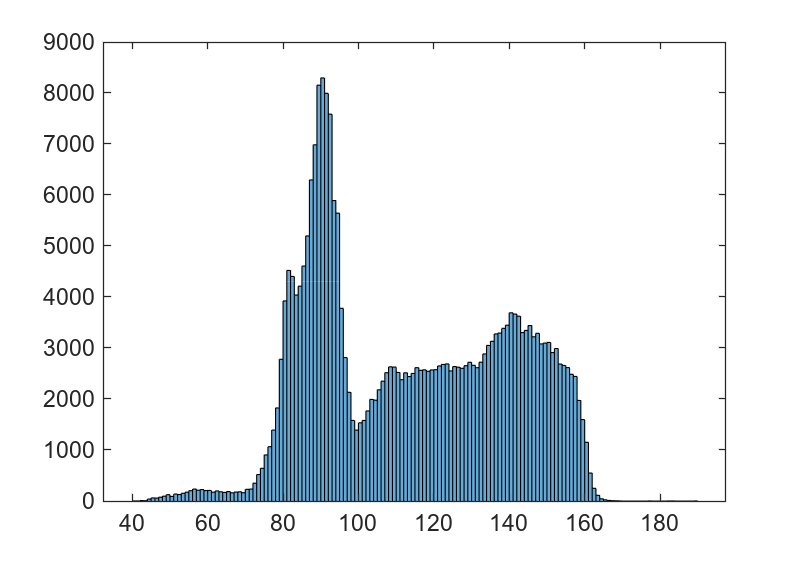

histogram(bild1);

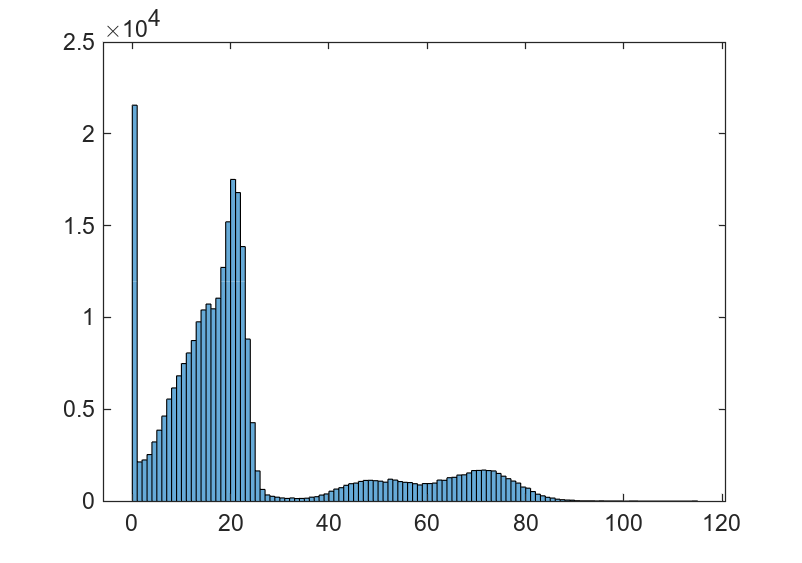

histogram(bild_sub);

% bild_sub = imsubtract(bild2, bild_sub);

M=graythresh(bild_sub)

M = 0.1490

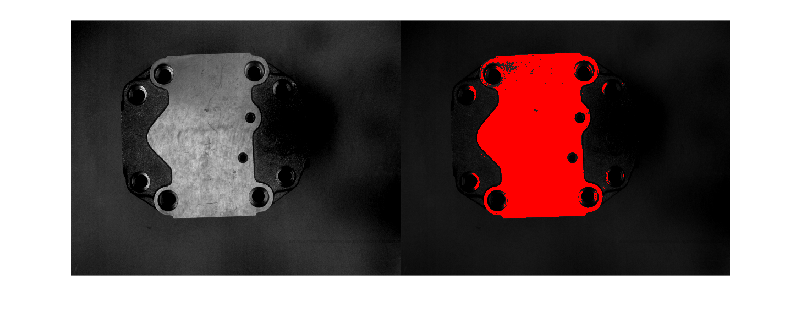

imb_1 = imbinarize(bild_sub,M);
imo_1 = imoverlay(bild_sub, imb_1, 'red');
imshowpair(bild_sub, imo_1,"montage");

an_1_1 = bwconncomp(imo_1)

an_1_1 = struct with fields:
    Connectivity: 26
       ImageSize: [464 599 3]
      NumObjects: 314
    PixelIdxList: {1×314 cell}


- Inwiefern wird die Segmentierung des Pumpengehäuses durch das Hintergrundbild vereinfacht? Warum ist diese Lösung weiterhin nicht ideal, und wie könnten Sie das Problem möglichst einfach beheben?

- 泵壳的分割在多大程度上被背景图像所简化？为什么这个解决方案仍然不理想，你怎么能尽可能容易地解决这个问题？

- Die Segmentierung des Pumpengehäuses bezieht sich auf den Prozess, bei dem ein bestimmtes Objekt, in diesem Fall das Pumpengehäuse, **im Bild von anderen Objekten abgegrenzt wird**. **Dies ist wichtig, um das Pumpengehäuse von anderen Teilen im Bild, wie zum Beispiel dem Hintergrund, zu unterscheiden.**

- Inwiefern die Segmentierung des Pumpengehäuses durch das Hintergrundbild vereinfacht wird, hängt davon ab, wie gut das Hintergrundbild zu dem Pumpengehäuse passt. **Wenn das Hintergrundbild eine einfache, homogene Struktur hat, die sich deutlich von dem Pumpengehäuse unterscheidet, kann es dazu beitragen, die Segmentierung zu vereinfachen**. In diesem Fall könnten Computer Vision-Algorithmen das Pumpengehäuse im Bild leichter erkennen, indem sie die Bereiche des Bildes identifizieren, die dem Hintergrund entsprechen, und diejenigen Bereiche ignorieren, die sich von dem Hintergrund unterscheiden.

- Diese Lösung ist jedoch nicht ideal, da sie davon abhängt, dass das Hintergrundbild gut zum Pumpengehäuse passt. Wenn das Hintergrundbild zu komplex oder unregelmäßig ist, kann es schwierig werden, das Pumpengehäuse im Bild zu segmentieren. In solchen Fällen können die Algorithmen Schwierigkeiten haben, das Pumpengehäuse von dem Hintergrund abzugrenzen, was zu ungenauen Ergebnissen führen kann.

- Eine Möglichkeit, das Problem zu beheben, wäre die Verwendung von Bildverarbeitungsalgorithmen, die in der Lage sind, das Pumpengehäuse anhand von **Merkmalen wie Kanten, Texturen oder Farben zu erkennen und zu segmentieren**, auch ohne das Hintergrundbild. Diese Algorithmen sind in der Regel robuster und genauer als diejenigen, die auf der Verwendung des Hintergrundbilds basieren. Um diese Lösung möglichst einfach zu implementieren, könnten Sie eine entsprechende Software verwenden, die bereits mit solchen Algorithmen ausgestattet ist, anstatt sie selbst zu entwickeln.

- Eine bessere Lösung bietet in diesem Fall die Maske in „Bild 3“. Nutzen Sie sie, um das Pumpengehäuse mit Hilfe von Bildarithmetik (`immultiply`) aus dem Originalbild auszuschneiden, und beurteilen Sie das Ergebnis. Funktioniert dieses Verfahren auch, wenn Sie statt des Pumpengehäuses in „Bild 1“ das „Bild 4“ verwenden?

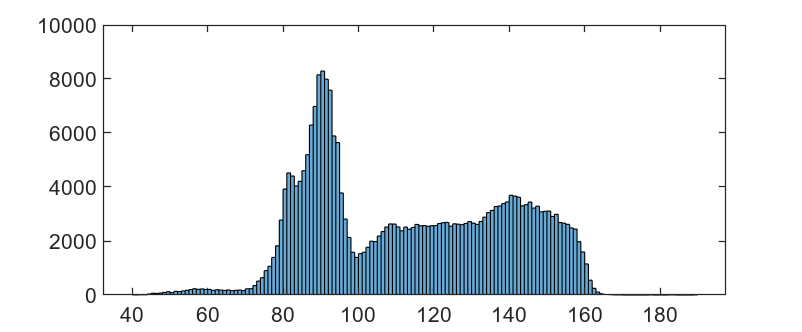

% 乘法运算可以实现掩模处理，即屏蔽掉图像的某些部分,屏蔽的部分用0表示
% 一幅图像乘以一个常数通常被称为缩放。如果使用的缩放因数大于 1，那么将增强图像的亮度；如果因数小于1，则会使图像变暗。
% i16 = uint16(bild3); % 创建圆盘半径15
bild_mul = immultiply(bild1, bild3);
bild_sub1 = bild1 - bild_mul;
% background = imopen(bild2,strel('disk',20)); % 创建圆盘半径1

histogram(bild1);

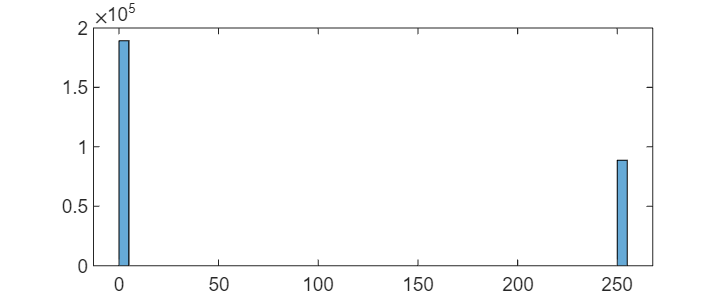

histogram(bild_mul);

M1 = graythresh(bild_mul)

M1 = 0.4980

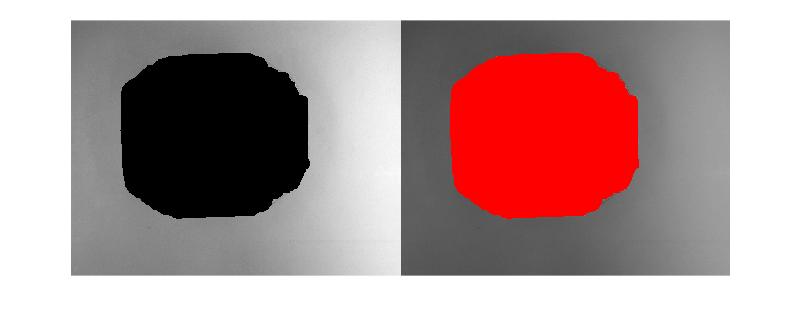

imb_2 = imbinarize(bild_mul, M1);

imo_2 = imoverlay(bild1, bild3, 'red');
imshowpair(bild_sub1, imo_2, "montage");

an_1_1 = bwconncomp(imo_2)

an_1_1 = struct with fields:
    Connectivity: 26
       ImageSize: [464 599 3]
      NumObjects: 1
    PixelIdxList: {[656442×1 double]}


**Bonusaufgabe:** Subtrahieren Sie „Bild 1“ und „Bild 4“ und markieren Sie die Unterschiede mittels `imbinarize`. Was für Informationen könnten Sie aus diesem Bild entnehmen?

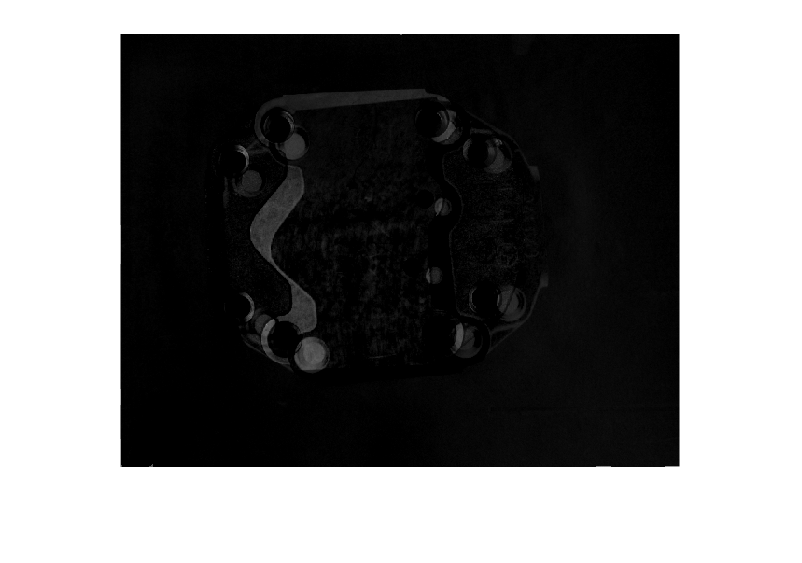

% background=imopen(bild1,strel('disk',15)); % 创建圆盘半径15
bild_sub = imsubtract(bild1, bild4);

imshow(bild_sub);

M=graythresh(bild_sub)

M = 0.0941

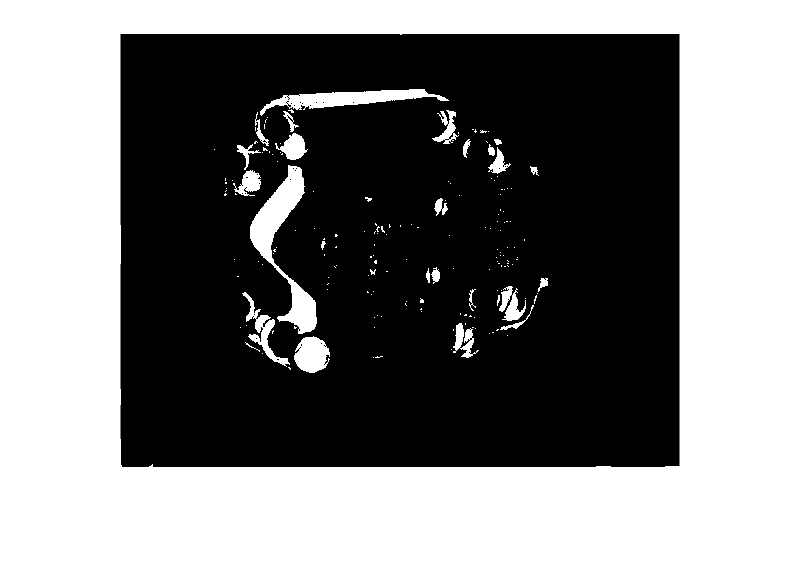

imb_1 = imbinarize(bild_sub,M);
imshow(imb_1)

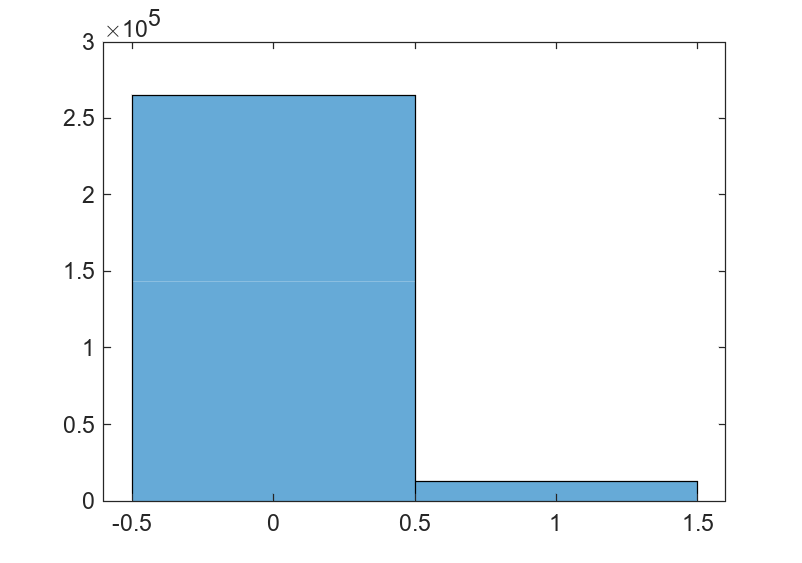

histogram(imb_1)

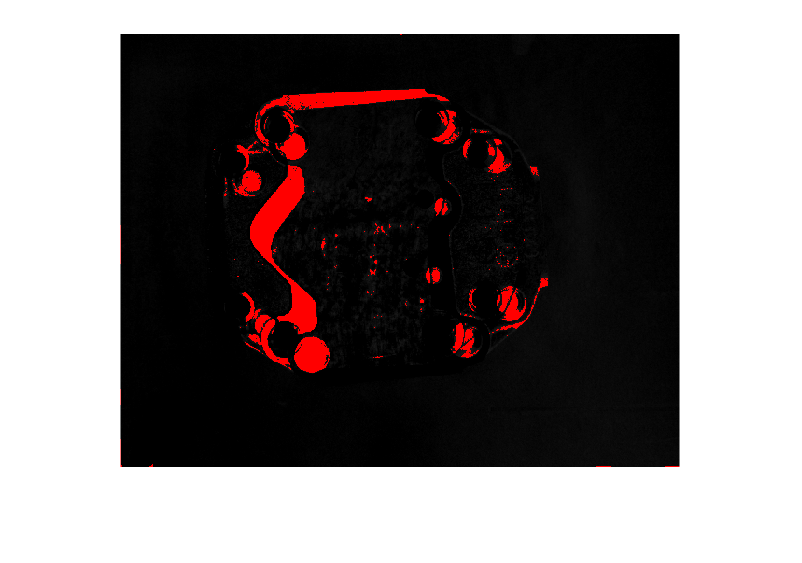

imo_1 = imoverlay(bild_sub, imb_1, 'red');
imshow(imo_1);

an_1_1 = bwconncomp(imo_1)

an_1_1 = struct with fields:
    Connectivity: 26
       ImageSize: [464 599 3]
      NumObjects: 1822
    PixelIdxList: {1×1822 cell}


**3 Segmentierung, Morphologische Operationen, LookUp-Tables (ca. 45-60 Min)**

Das Pumpengehäuse war nicht allein auf Basis der Grauwerte zu segmentieren. Nun schauen wir uns einen Fall an, in dem zwar ein Schwellwertoperator zur Segmentierung genutzt werden kann, jedoch eine Nachbearbeitung mittels morphologischen Operatoren notwendig ist. Nutzen Sie das Bild „Leiterplatte“.

仅仅根据灰度值，无法对泵壳进行分割。现在让我们看一下这样一种情况：阈值算子可以用于分割，但使用形态学算子进行后处理是必要的。使用图像 "印刷电路板"。

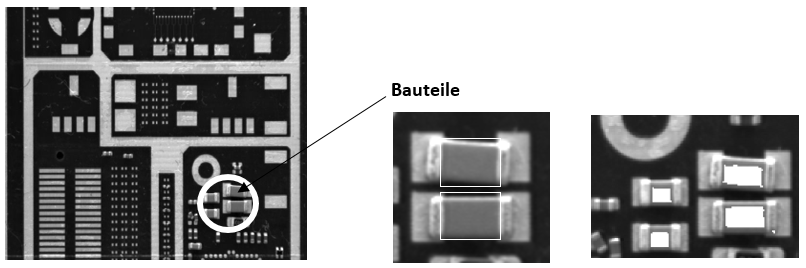

- Erstellen Sie ein Skript, das die Flächen der vier größeren Bauteile (Nur die im Bild weiß umrandete Fläche in der Mitte der Bauteile, nicht die Kontakte links und rechts an den Bauteilen) unabhängig von der Lage der Bauteile segmentiert. Nutzen Sie die bisher kennengelernten Werkzeuge, um eine Segmentierung mittels Schwellwertoperation durchzuführen. Da `imbinarize` nur einen Schwellwert nutzt und deshalb graue Flächen nicht gleichzeitig von hellen und dunklen Flächen trennen kann, können Sie zwei Binärbilder mit unterschiedlichen Schwellwerten erzeugen und anschließend voneinander subtrahieren.

- 创建一个脚本，对四个较大的组件的区域进行分割（只有图片中用白色勾勒的组件中间的区域，而不是组件左右的触点），而不考虑组件的位置。使用你到目前为止所学的工具，通过阈值操作来进行分割。由于imbinarize只使用一个阈值，因此不能同时将灰色区域与明暗区域分开，你可以用不同的阈值创建两个二进制图像，然后将它们相互减去。

- Laden Sie das Bild in Ihr Skript und konvertieren Sie es in ein Graustufenbild. Dies können Sie beispielsweise mit der imbinarize Funktion in MATLAB oder der cvtColor Funktion in OpenCV durchführen.

- Wählen Sie zwei Schwellwerte, um das Bild in zwei Binärbilder zu unterteilen, die die hellen und dunklen Bereiche des Bildes repräsentieren. Sie können zum Beispiel den Schwellwert anhand von Histogrammanalysen oder mithilfe von Otsu's Methode automatisch bestimmen.

- Subtrahieren Sie die beiden Binärbilder voneinander, um die Flächen der vier größeren Bauteile zu isolieren. Die Flächen sollten jetzt in dem resultierenden Bild als weiße Bereiche dargestellt werden.

- Führen Sie eine Bilderosion durch, um kleine Lücken in den Flächen zu schließen und die Kanten der Bauteile zu glätten.

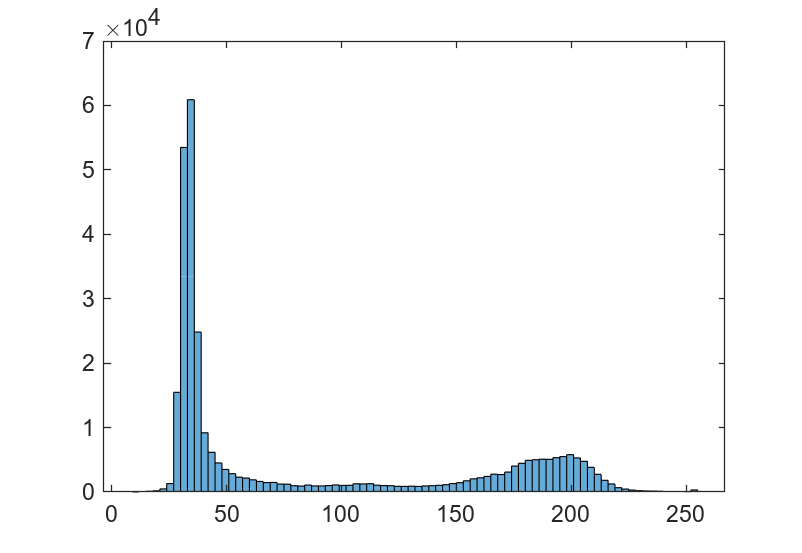

% Laden des Bildes
leiter = imread("Leiterplatte.png");
histogram(leiter)

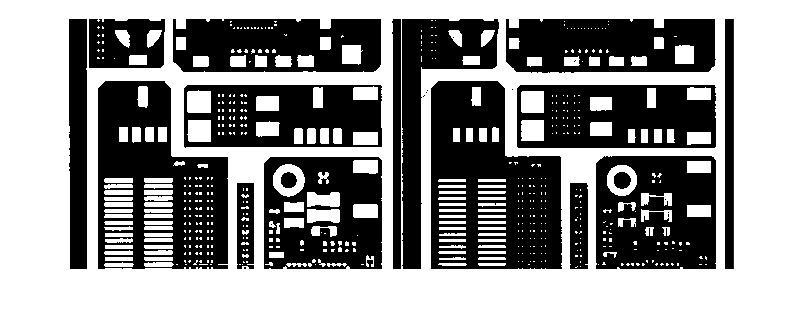

% Konvertieren des Bildes in Grauwertbild
% gray_img = rgb2gray(leiter);

% Konvertieren des Grauwertbildes in Binärbild
bw1 = imbinarize(leiter, 80/255);
bw2 = imbinarize(leiter, 140/255);
imshowpair(bw1, bw2, "montage")

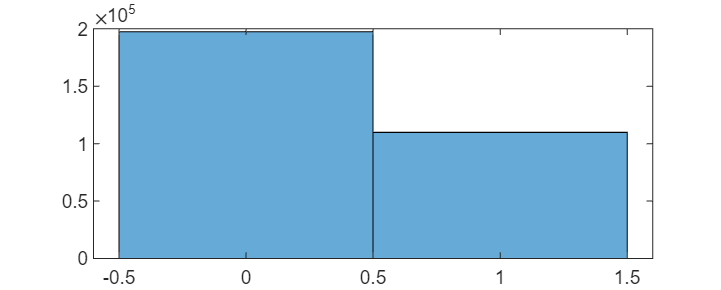

histogram(bw1)

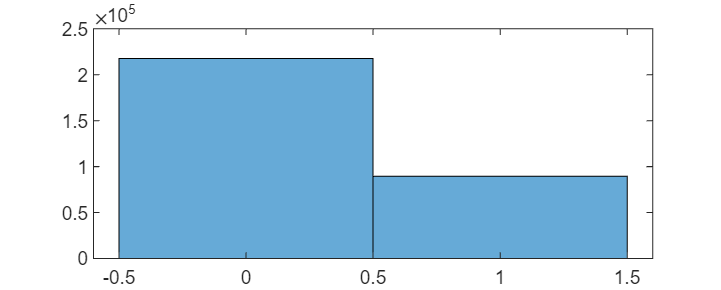

histogram(bw2)

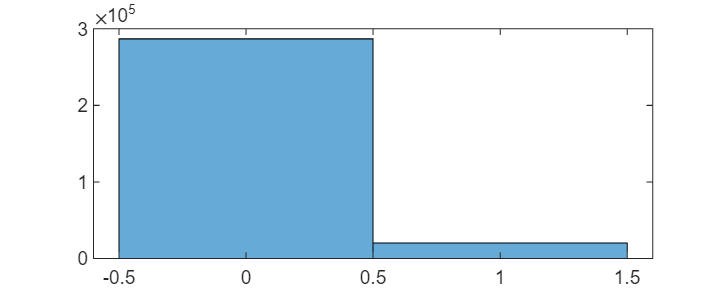

bw = bw1 - bw2;
histogram(bw)


SE = strel("rectangle",[5 2])

SE = strel is a rectangle shaped structuring element with properties:

      Neighborhood: [5×2 logical]
    Dimensionality: 2


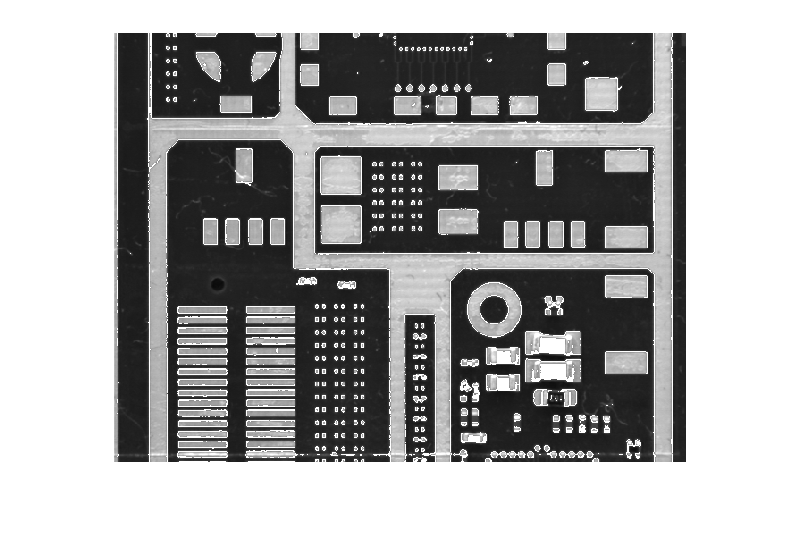

%  leiter1 = leiter > 100;
%  imshow(leiter1)
%  M = graythresh(leiter)
% %  bi1 = imbinarize(leiter,M);
% %  bi2 = ~imbinarize(leiter,M);
% %  imshow(bi1)
% %  bild_sub1 = imsubtract(leiter, bi1);
% %  bild_mul1 = immultiply(leiter, bi1);
%  bi1 = leiter > 220;
%  bi2 = leiter < 100;
%  imshowpair(bi1,bi2,'montage');
%  mul1 = immultiply(leiter, maskedImage);
% 
%  sub1 = imsubtract(leiter, maskedImage);
%  imshowpair(mul1, sub1,'montage');
% %  bild_sub1 = bi1 - bi2;
%  imshow(bild_sub1);
imo = imoverlay(leiter, bw, [1 1 1]);
imshow(imo)

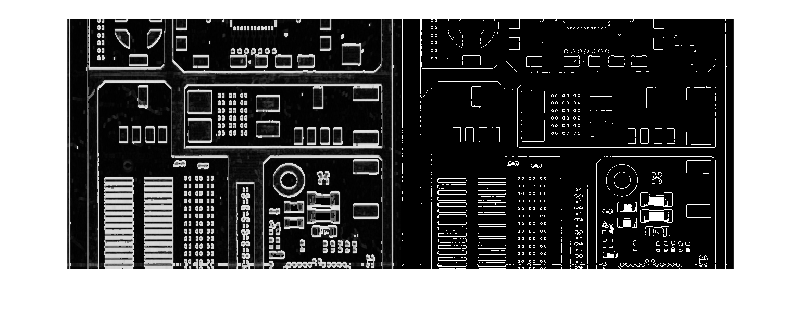


max = imdilate(imo, strel("rectangle",[5 2]));
min = imerode(imo, strel("rectangle",[5 2]));
max_min = max - min;
% min_max = min - max;

% bw_mul = immultiply(leiter,bw) ;
imshowpair(max_min, bw, 'montage');

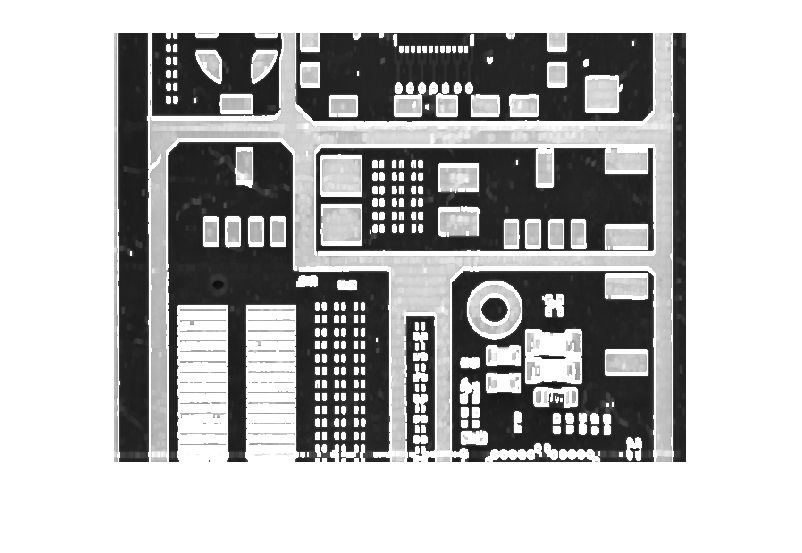


%  % 使用结构元素 SE 膨胀灰度、二值或压缩二值图像 I。
 max = imdilate(imo, strel("rectangle",[5 2]));
 imshow(max)

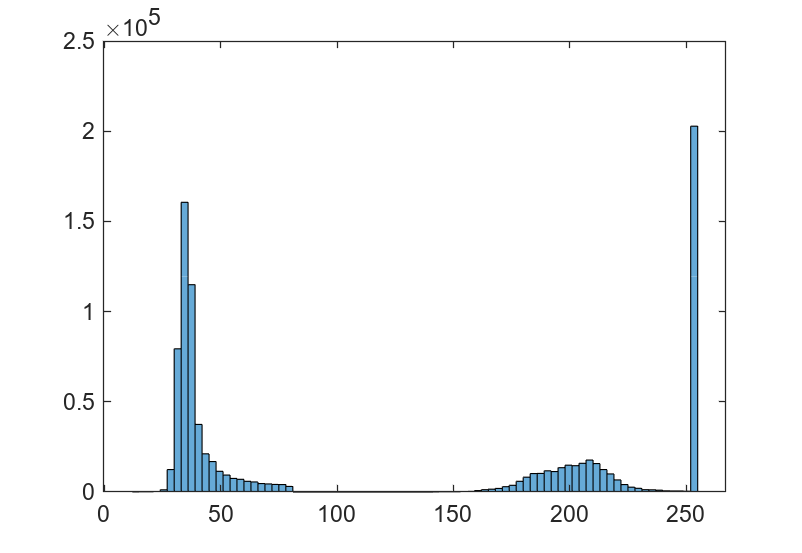

 histogram(max)

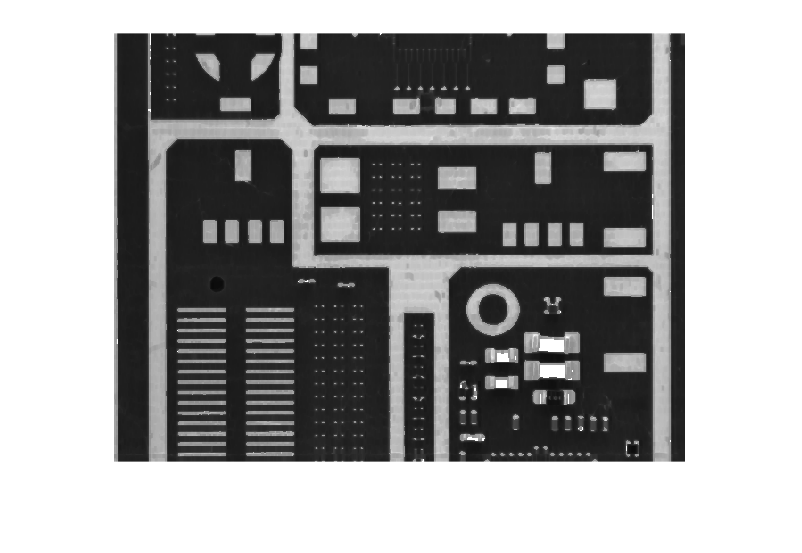

 min = imerode(imo, strel("rectangle",[5 2]));
 imshow(min)

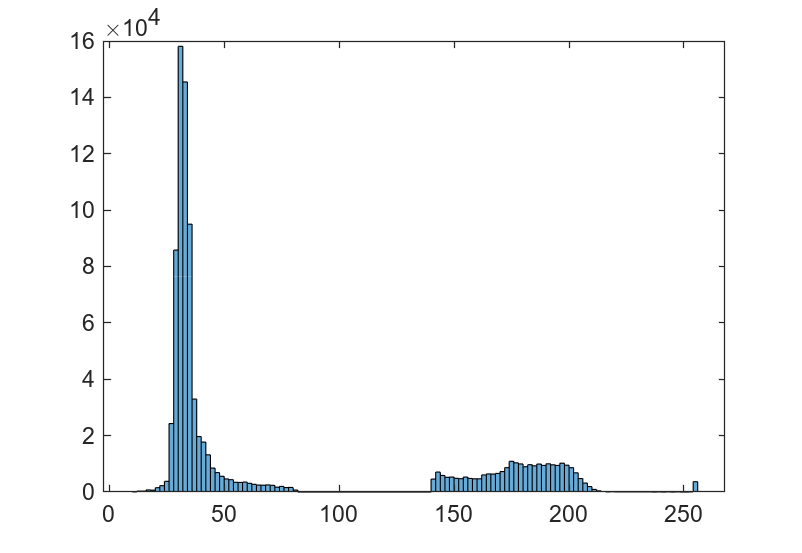

 histogram(min)

%  imshowpair(max, min,'montage');

- Entfernen Sie übrig bleibende Artefakte anschließend mit Hilfe von morphologischen Funktionen.

- 事后在形态学功能的帮助下去除剩余的人工痕迹。

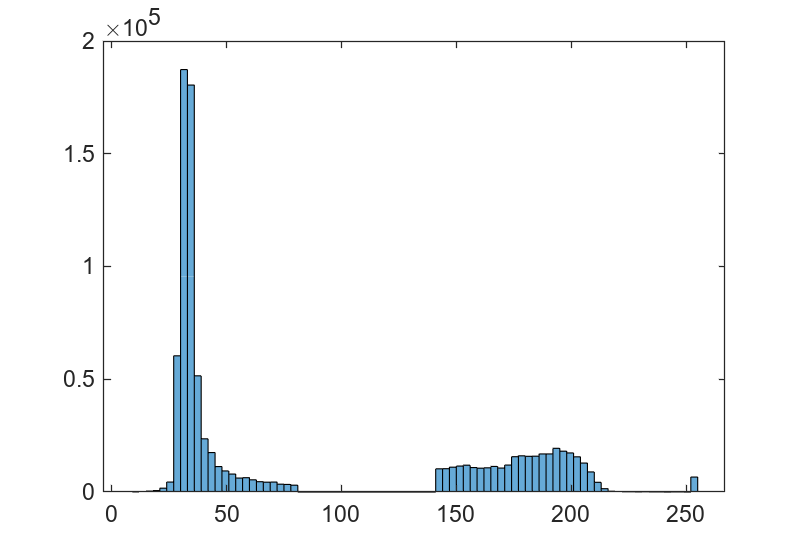

op = imopen(imo, SE); 
clo = imclose(imo, SE);
%  mu = immultiply(bi2, clo);
histogram(op)

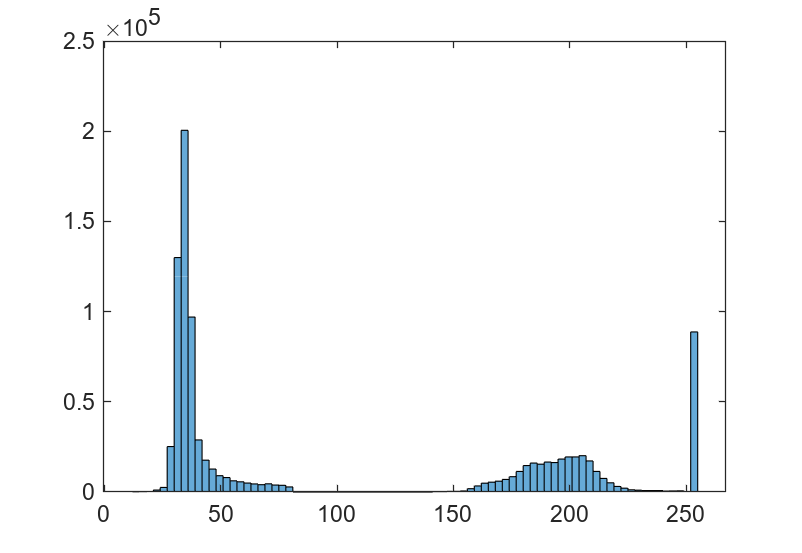

histogram(clo)

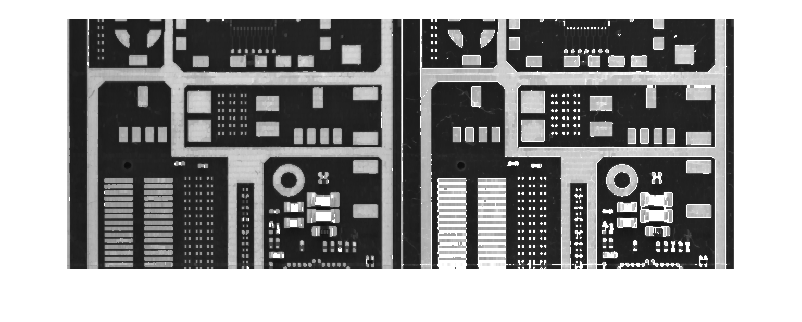

 imshowpair(op, clo,'montage');

**Bonusaufgabe:** Heben Sie die Flächen der Bauteile im Originalbild hervor, indem Sie sie weiß markieren (wie im rechten Bild).

用白色标记突出原始图像中的组件区域（如右边的图像）。

- Lassen Sie sich das Histogramm zum Originalbild „Leiterplatte“ anzeigen. Wie Sie sehen, wird das vorhandene Spektrum an Grauwerten schlecht ausgenutzt. Der Kontrast in den hellen und dunklen Bereichen ist daher jeweils nicht optimal. Nutzen Sie `imadjust,` um den Kontrast einmal in dunklen und einmal in hellen Regionen zu verbessern, d.h. die Grauwertunterschiede im relevanten Bereich besser wahrnehmbar zu machen. Vollziehen Sie Ihre Auswahl nach, indem Sie den funktionalen Zusammenhang zwischen Originalgrauwert und Ergebnisgrauwert skizzieren!

- 显示原始图像 "印制电路板 "的直方图。正如你所看到的，可用的灰度值光谱利用得很差。因此，亮部和暗部的对比并不理想。使用imadjust在暗区和亮区各改善一次对比度，即让相关区域的灰度值差异更容易被感知。通过勾画出原始灰度值和结果灰度值之间的功能关系来重建你的选择

- Finden Sie auch eine Funktion, die den Kontrast gleichzeitig sowohl in den hellen als auch in den dunklen Bereichen verbessert? Wie könnte der funktionale Zusammenhang in diesem konkreten Fall aussehen? Diskutieren Sie!

- 你还能找到一个能同时改善亮部和暗部对比度的功能吗？在这个具体案例中，功能关系可能是什么样子的？讨论一下!

- `imadjust` 通过将输入强度图像的值映射到新值来增加图像的对比度，从而默认情况下，在输入数据的低强度和高强度下，1％的数据处于饱和状态。

- `histeq`执行直方图均衡化。它通过转换强度图像中的值来增强图像的对比度，以使输出图像的直方图近似匹配指定的直方图（默认情况下为均匀分布）。

- `adapthisteq`执行对比度限制的自适应直方图均衡。与不同`histeq`，它在较小的数据区域（图块）而不是整个图像上运行。增强每个图块的对比度，以使每个输出区域的直方图近似匹配指定的直方图（默认情况下为均匀分布）。为了避免放大图像中可能存在的噪声，可以限制对比度增强。

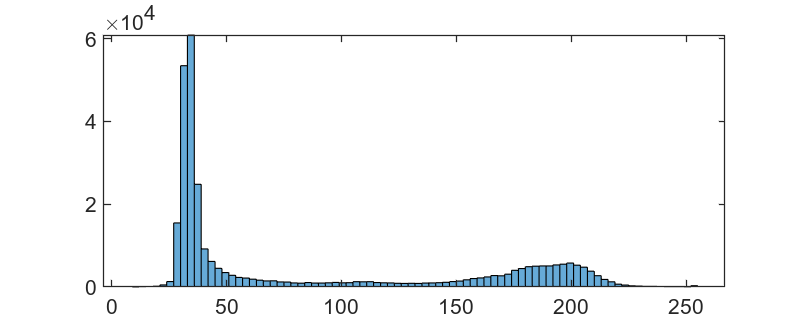

 histogram(leiter)

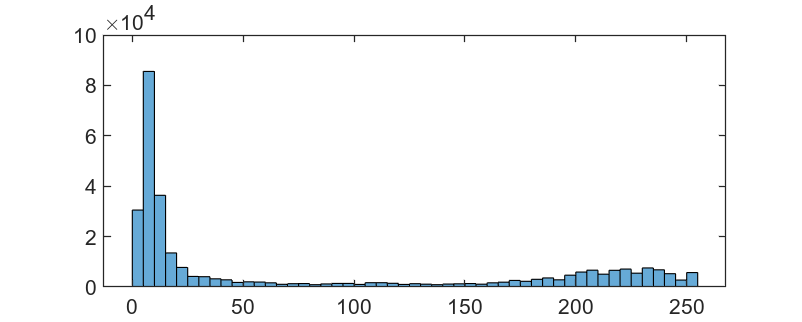

 adj = imadjust(leiter); %调整图像强度值或颜色图
 M=graythresh(adj);
 bi1 = imbinarize(adj,M);
 SE = strel("rectangle",[20 10]);
%  BWsdil = imdilate(bi1,SE);
%  op =imopen(bi1, strel("rectangle",[20 10])); 
%  mu = immultiply(adj, op)
 his = histeq(leiter);
%  imshow(mu)
%  adap = adapthisteq(leiter);
%  imshow(adap)
histogram(adj)

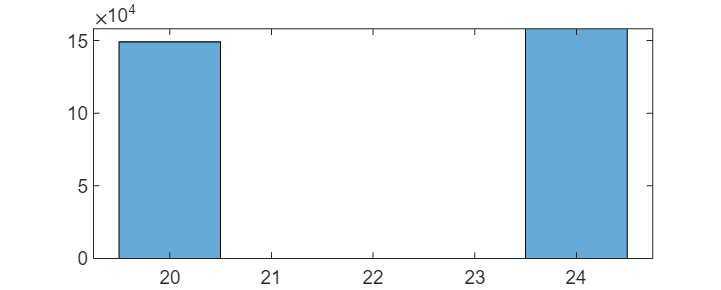

histogram(his)

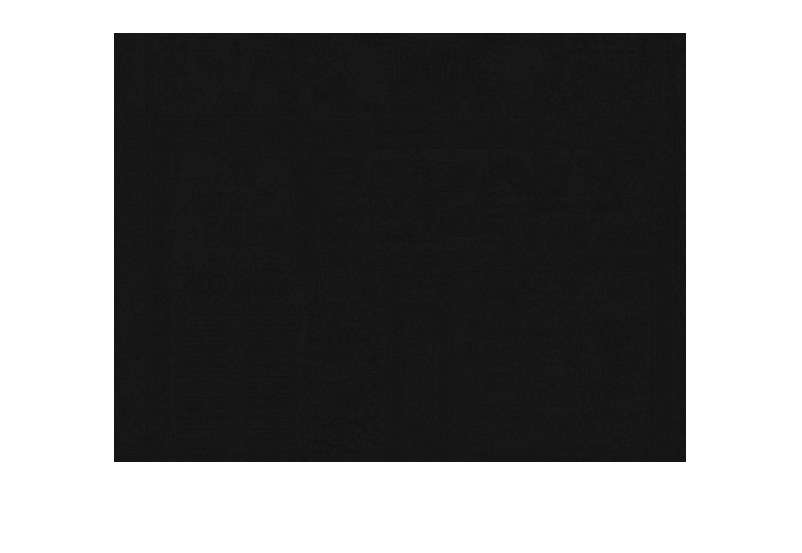

imshow(his)

%  histogram(his)
%  histogram(adap)
% imadjust sättigt die niedrigsten 1% und die höchsten 1% aller Pixelwerte.
% histeq so dass das Histogramm des ausgegebenen Graustufenbildes J 64 Bins hat und annähernd flach ist.